# Time course for the story

## Unstable oscillation

Delta_E = 0.12;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

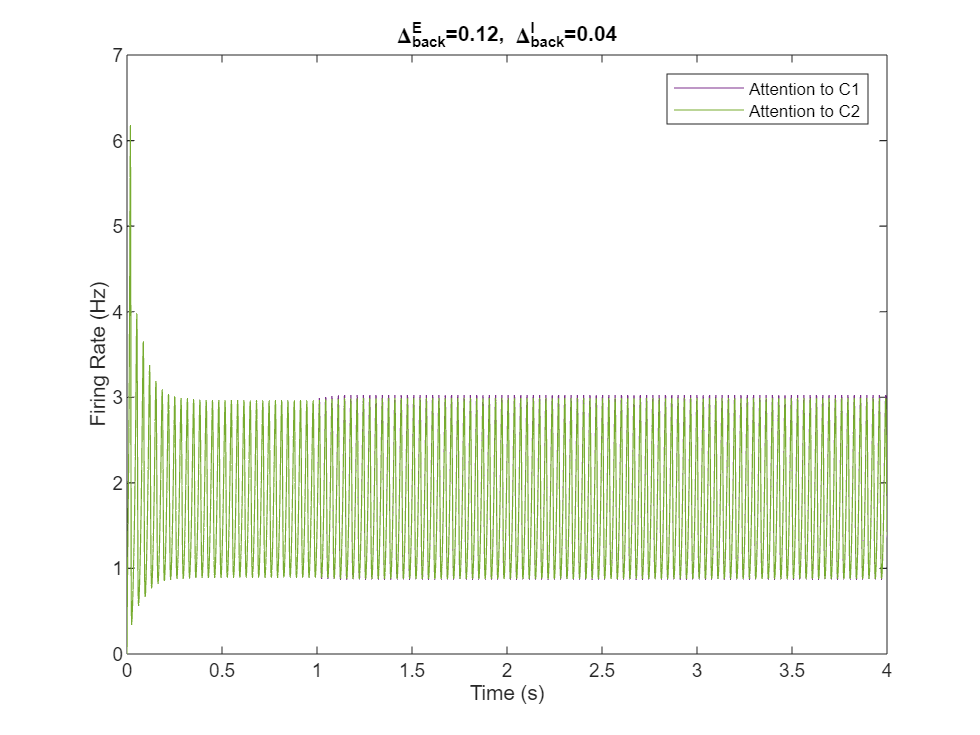

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;
% 
% recX = [1 time/1000 time/1000 1];
% recY = [0 0 100 100];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

% axis([0 time/1000 9 16]);
xlabel("Time (s)");
ylabel("Firing Rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);


% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

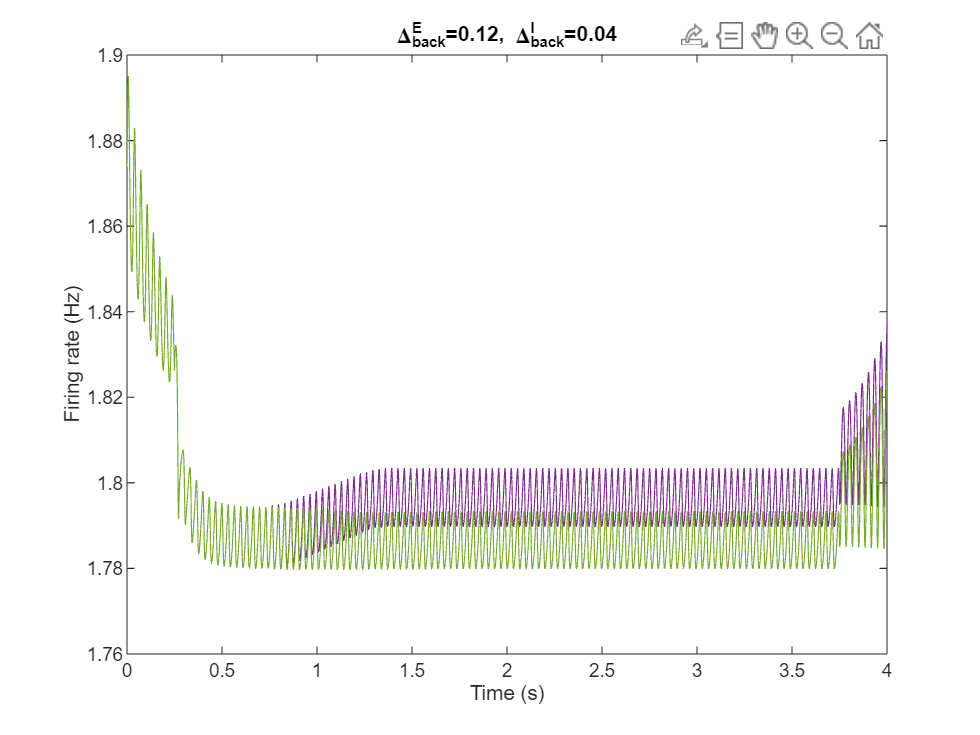

va = 50000;
fs = 1000;
r_cond4 = movmean(squeeze(r(1,:,4)),va);
r_cond5 = movmean(squeeze(r(1,:,5)),va);
% r_cond4 = lowpass(squeeze(r(1,:,4)),1,100000);
% r_cond5 = lowpass(squeeze(r(1,:,5)),1,100000);
figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 100 100];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

% axis([0 time/1000 0 10]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

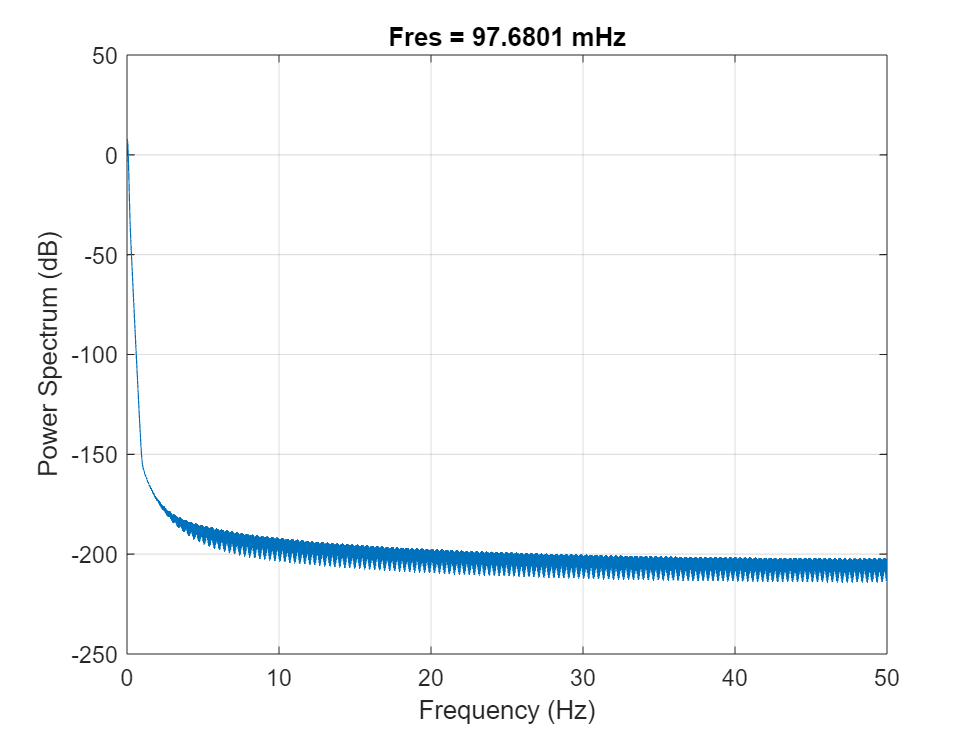

figure();
fs = 100;
r_cond4 = squeeze(r(1,:,4));
pspectrum(r_cond4,fs);

% figure();
% pop = 1;
% tmp1 = squeeze(r(pop,50001:100000,1)); tmp5 = squeeze(r(pop,350001:400000,4));
% tmp6 = squeeze(r(pop,350001:400000,5));
% levels = mean([tmp1 tmp5 tmp6]);
% level_norm = normBetween01(level,1);
% 
% plot([1 2 3], level(pop_E,[1 5 6]),'Color',colors(layer), 'LineWidth',1);
% 
% ylabel("Normalized firing rate");
% xlabel("Conditions");
% xticks([1 2 3 4 5 6]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% title("Normalized firing rate by conditions",'FontSize',12);
% 
% set(gca, 'FontName', 'Arial');
% filename = append(figpath,'fr_','all');
% print(filename, '-dpng', '-r600');

## Sensory only WTA of L2/3E

Delta_E = 0.12;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

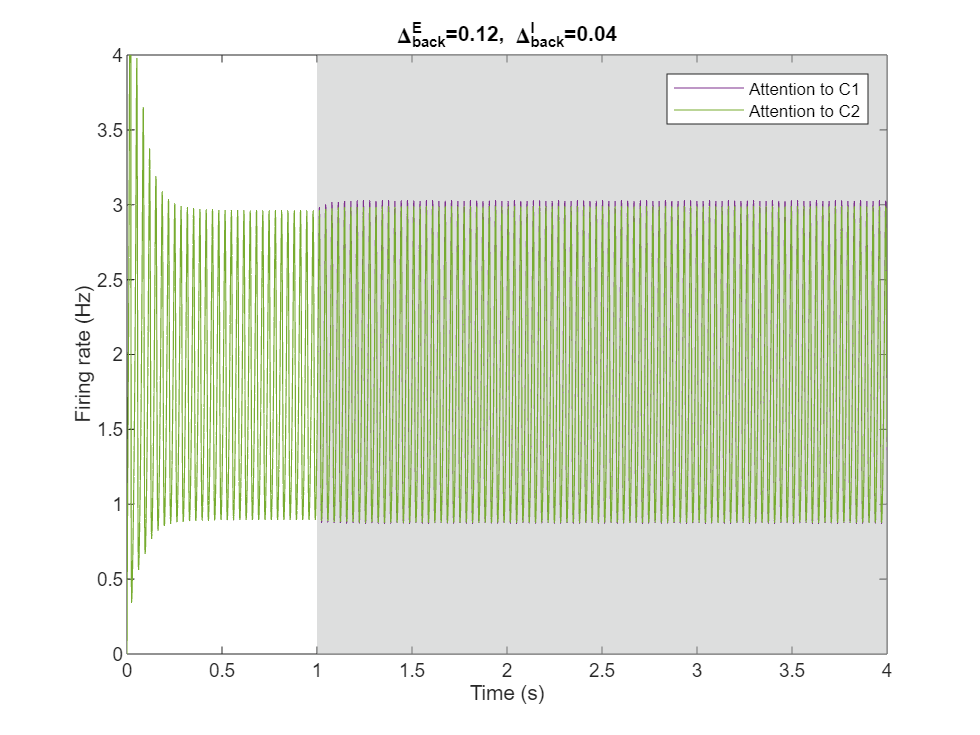

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

axis([0 time/1000 0 4]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

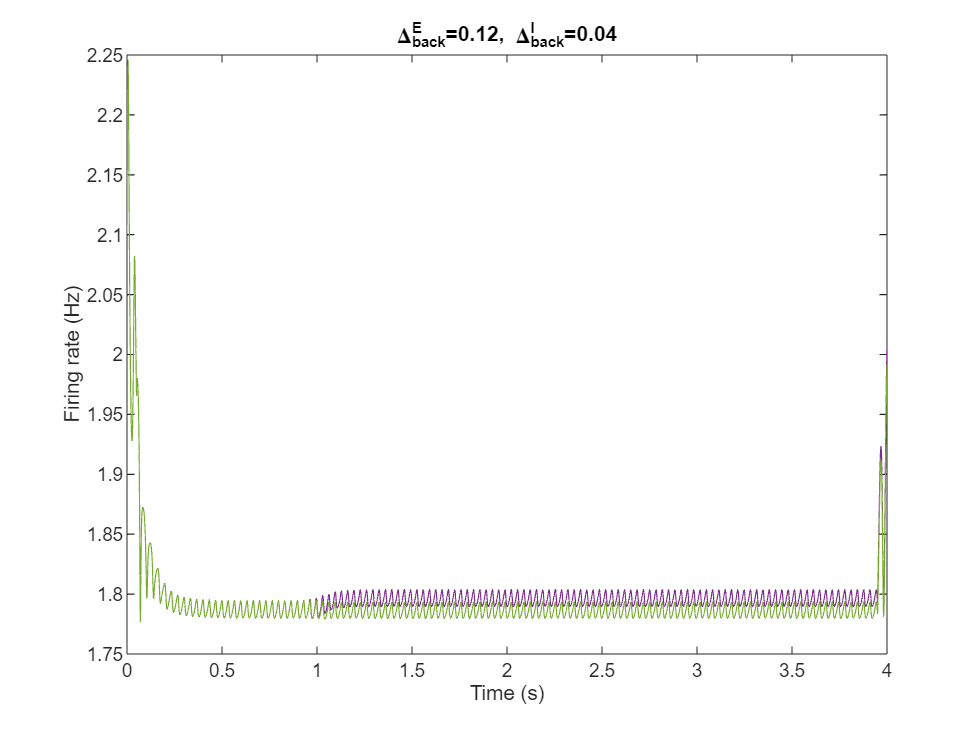

va = 100*100;
r_cond4 = movmean(squeeze(r(1,:,4)),va);
r_cond5 = movmean(squeeze(r(1,:,5)),va);
figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 100 100];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);

% axis([0 time/1000 2.6 2.8]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');


## Sensory only WTA of L2/3E counterexample

Delta_E = 0.2;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

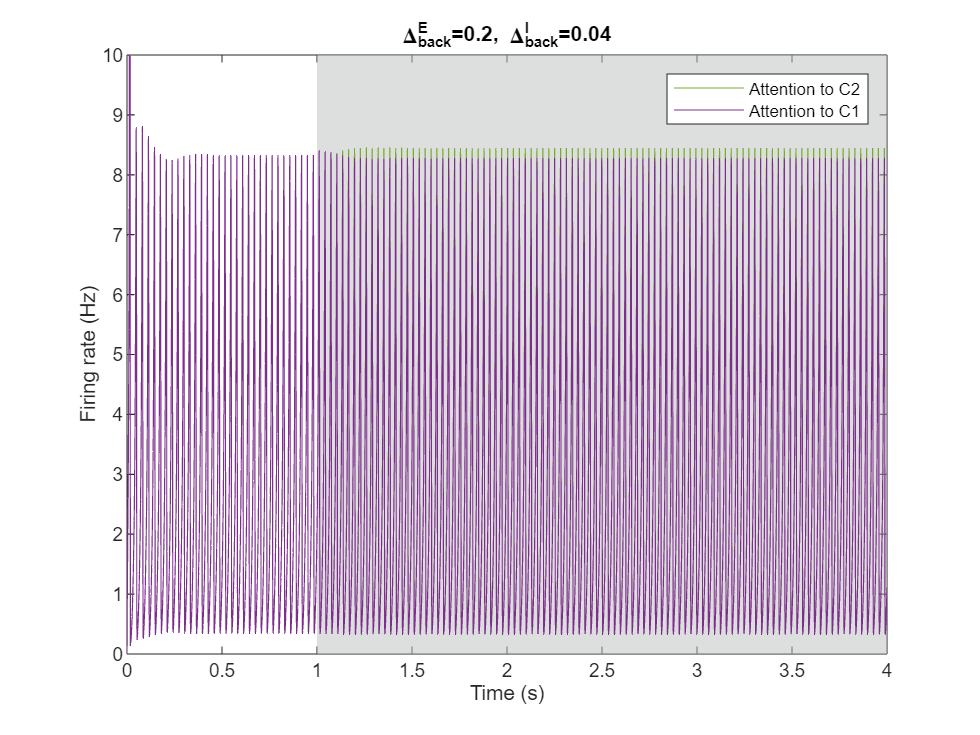

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);


axis([0 time/1000 0 10]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C2","Attention to C1"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

## attention only + sensory & attention anti-WTA

Delta_E = 0.15;
Delta_I = 0.044;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

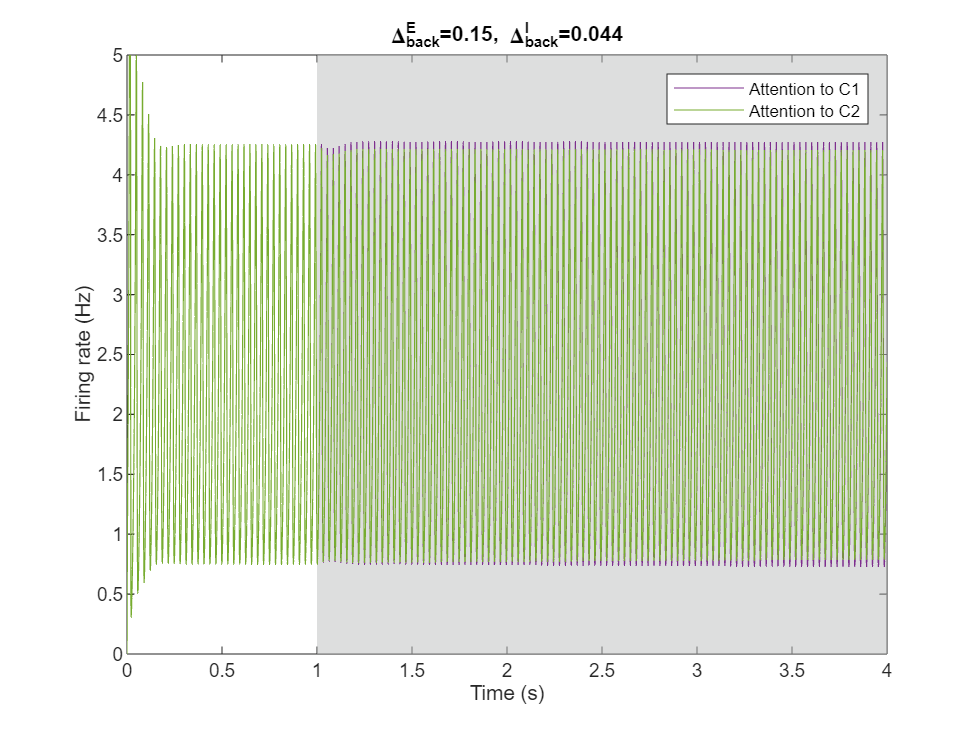

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);


axis([0 time/1000 0 5]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

Delta_E = 0.2;
Delta_I = 0.027;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

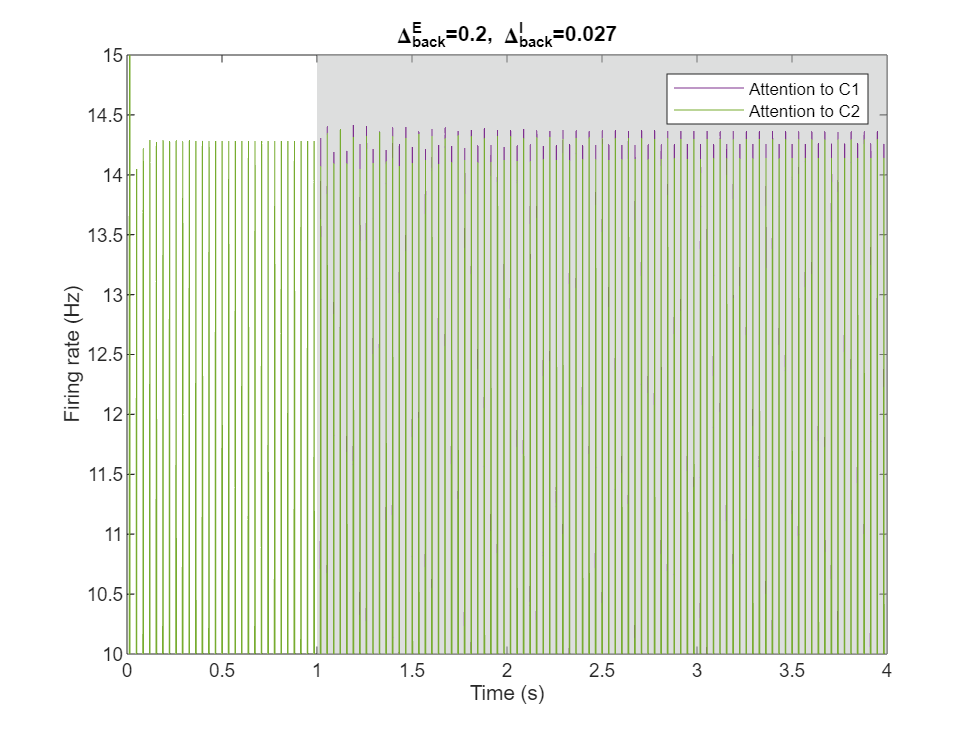

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);


axis([0 time/1000 10 15]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');


Delta_E = 0.37;
Delta_I = 0.04;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

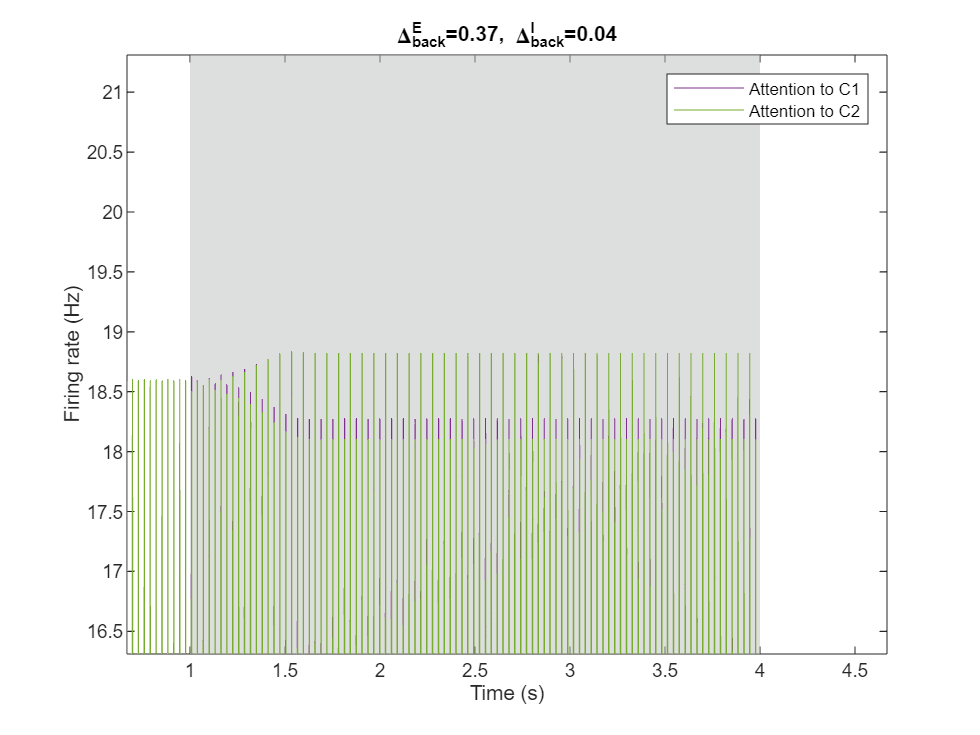

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);


axis([0 time/1000 10 15]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');

## **

Delta_E = 0.1;
Delta_I = 0.03;
Iattn = 0.02;
time = 4000;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time);
r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

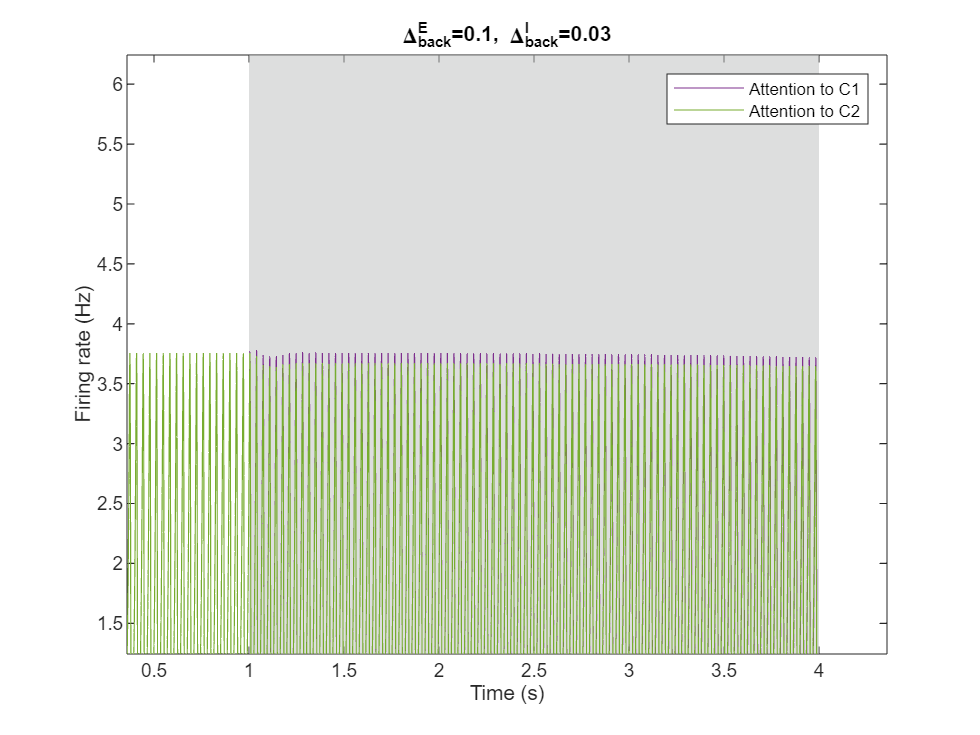

r_cond4 = squeeze(r(1,:,4));
r_cond5 = squeeze(r(1,:,5));
figure();

hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 100 100];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.5);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.5);


axis([0 time/1000 10 15]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
title(append("\Delta_{back}^E=",num2str(Delta_E), ", \Delta_{back}^I=",num2str(Delta_I)));
box on;
legend(["","Attention to C1","Attention to C2"]);
% x0 = 0; y0 = 0; width = 6; height = 2;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% print('rawC', '-dpng', '-r600');
% print('rawC', '-depsc', '-r600');